cd('G:\My Drive\Matlab_work\BC\SMIIL\SeniorSeminar\Data_Analysis\Data')
load PondData.mat
load Met.mat
cd('G:\My Drive\Matlab_work\BC\SMIIL\SeniorSeminar\Data_Analysis')
load HOBO.mat

% Met variables in kms units

met.dn = datenum(met.DateTime);
met.airtemp_C = (5/9)*(met.AirTempF-32); % Celsius = (5/9)*(Fahrenheit-32); 
met.windspeed_ms = met.WindSpeed_mph*1609.34/3600; % mph --> m/s
met.Precip_cm = met.Precip_in/2.54; % inches to cm of rain
%Windspeed to time of pond measurements 
pond.windspeed_ms = interp1(met.dn,met.windspeed_ms,pond.dn);

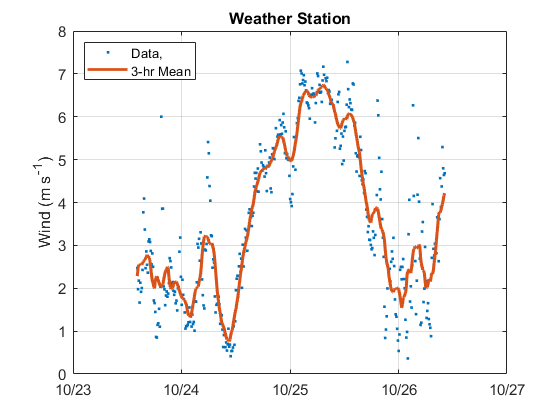


% For wind measurements (U10) and water measurements (Cw)
nm = 18; % number of points for moving mean
U10 = movmean(pond.windspeed_ms,nm); % m/s  

figure
plot(pond.dn,pond.windspeed_ms,'.')
hold on
plot(pond.dn,U10,'LineWidth',2)
ylabel('Wind (m s^-^1)')
datetick
grid on
title('Weather Station')
legend('Data,','3-hr Mean','Location','NW')

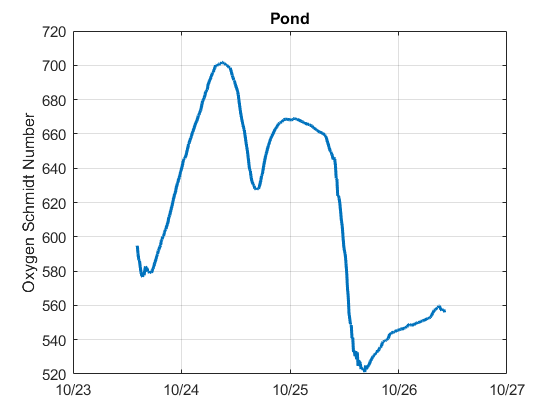



%Calculate Oxygen Schmidt number for pond water 
% From Cara's toolbox
% This was not as straight forward as I thought and slightly different
% results for different calculations
[D_DO, Sc_DO] = gasmoldiff(pond.sal,pond.temp,'O2');

figure
plot(pond.dn,Sc_DO,'Linewidth',2)
ylabel('Oxygen Schmidt Number')
title('Pond')
datetick
grid on

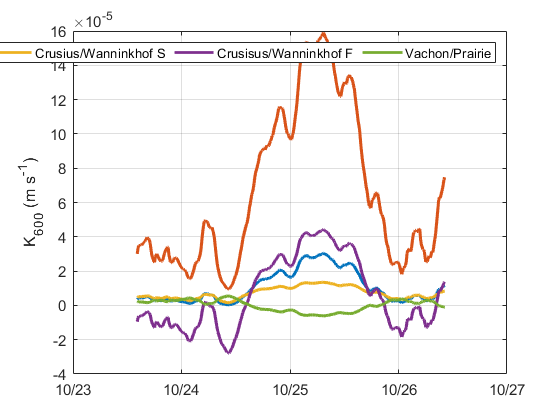


% Gas paramertization for CO2 in freshwater (Vachon and Prarie - 2013)
LA = 2.6013e-6; % in sq. km ( = ~ 28 sq ft)

% Air-sea parameterizations (cm/hr) and converted to m/s
k1 = (0.24*(U10.^2))/100/3600; % Wanninkhof (2014)
k2 = (2.07 + 2.15*(U10.^1.7))/100/3600; % Cole and Caraco (1998)
k3 = (0.72*U10)/100/3600; % Crusius and Wanninkhof (2014) U < 3.7 m/s
k4 = (-13.3 + 4.33*U10)/100/3600; % Crusius and Wanninkhof (2014) U > 3.7 m/s
k5 = (2.51 + 1.48*U10 + 0.39*U10.*log10(LA))/100/3600; %Vachon and Prairie (2013)


figure
plot(pond.dn,k1,'LineWidth',2)
hold on
plot(pond.dn,k2,'LineWidth',2)
plot(pond.dn,k3,'LineWidth',2)
plot(pond.dn,k4,'LineWidth',2)
plot(pond.dn,k5,'LineWidth',2)
ylabel('K_6_0_0 (m s^-^1)')
datetick
grid on
legend('Wanninkhof','Cole/Caraco','Crusius/Wanninkhof S','Crusisus/Wanninkhof F','Vachon/Prairie',...
    'Location','north','Orientation','Horizontal')

- Vachon and Prairie (2013) was the best for the Howard (2018) paper looking at air-sea gas exchange at the PIE LTER for most gases (pond = 7000m2). 

- Here it ends up with a negative results because of the scaling to Surface Area that ends up being negative with the log scale in the equation. 

- Howard (2018) found that Cole and Caraco was best for Xe.  

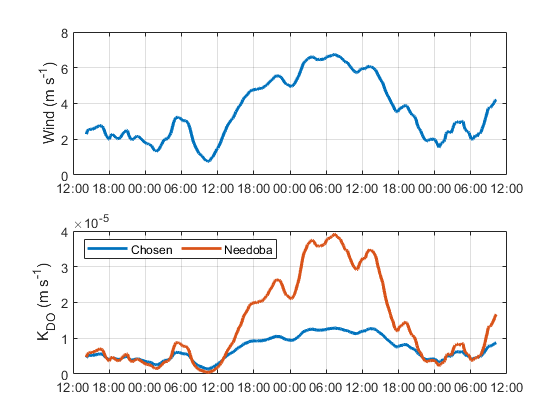

% Convert from CO2 referenced equation (k600) to O2 with Schmidt number ratio
k_picked = k3; % Chosen parameterization
k = (Sc_DO/600).^-0.5 .*k_picked; % units same as wind speed 
k6 = (0.31*(U10.^2).*((Sc_DO/660).^-0.5))/100/3600; % Needoba Chapter m/s

figure
subplot(2,1,1)
plot(pond.dn,U10,'Linewidth',2)
ylabel('Wind (m s^-^1)')
datetick
grid on

subplot(2,1,2)
plot(pond.dn,k,'Linewidth',2)
hold on
plot(pond.dn,k6,'Linewidth',2)
ylabel('K_D_O (m s^-^1)')
datetick
grid on
legend('Chosen','Needoba','Location','NW','Orientation','Horizontal')

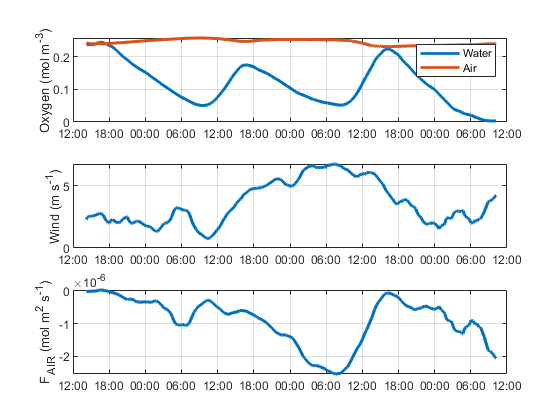

% Calculate air sea gas exchange 
Ca = gasmoleq(pond.sal,pond.temp,'O2'); % mol/m3
Cw = movmean(pond.DOmeas,nm); % mol/m3      % *** nm is assigned with windspeed smoothing above 
Fair0 = k.*(Cw - Ca); %

figure
subplot(3,1,1)
plot(pond.dn,Cw,'Linewidth',2)
hold on
plot(pond.dn,Ca,'Linewidth',2)
ylabel('Oxygen (mol m^-^3)')
legend('Water','Air')
datetick
grid on

subplot(3,1,2)
plot(pond.dn,U10,'Linewidth',2)
ylabel('Wind (m s^-^1)')
datetick
grid on

subplot(3,1,3)
plot(pond.dn,Fair0,'Linewidth',2)
ylabel('F_A_I_R (mol m^2 s^-^1)')
datetick
grid on

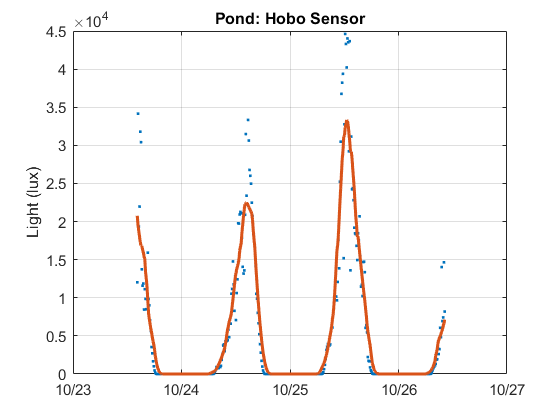

% Find when daylight and when night time
%  Put the Hobo light data on the same time record as the Pond YSI

pond.light_lux = interp1(hobo.dn,hobo.light_lux,pond.dn);
PM = find(pond.light_lux < 0.15); % Find all values where light lux = 0 (night time)
AM = find(pond.light_lux > 0.15); % Find all values where light lux is not = 0 (day time)
 % have to use 0.15 and not zero because some noise in our readings around

figure
plot(pond.dn,pond.light_lux,'.')
hold on
plot(pond.dn,movmean(pond.light_lux,nm),'Linewidth',2)
ylabel('Light (lux)')
datetick
grid on
title('Pond: Hobo Sensor')

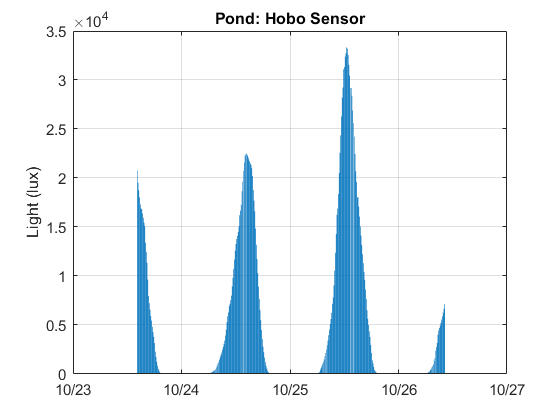


figure
bar(pond.dn,movmean(pond.light_lux,nm))
ylabel('Light (lux)')
datetick
grid on
title('Pond: Hobo Sensor')

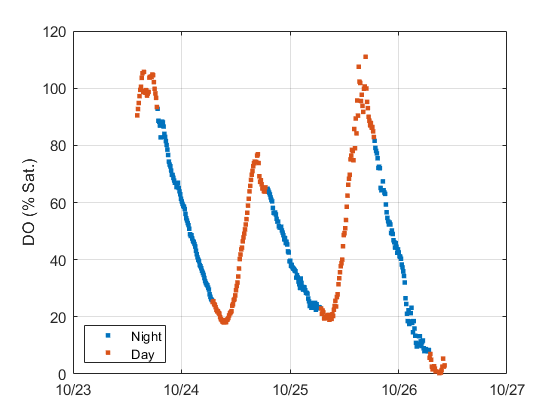

figure
plot(pond.dn(PM),pond.DOper(PM),'.','MarkerSize',10)
hold on
plot(pond.dn(AM),pond.DOper(AM),'.','MarkerSize',10)
datetick
grid on
ylabel('DO (% Sat.)')
legend('Night','Day','Location','SW')
ylim([0 120])

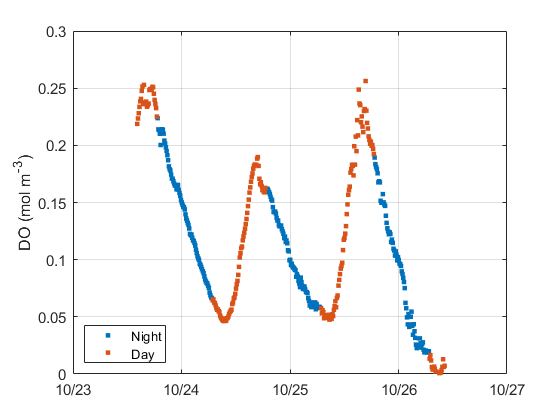


figure
plot(pond.dn(PM),pond.DOmeas(PM),'.','MarkerSize',10)
hold on
plot(pond.dn(AM),pond.DOmeas(AM),'.','MarkerSize',10)
datetick
grid on
ylabel('DO (mol m^-^3)')
legend('Night','Day','Location','SW')
ylim([0 0.3])

AMflux = AM(2:end-1); % t2-t1 for flux (remove first AM point)
PMflux = PM;
%Convert to mmol/m2/hr 
Fair = Fair0(2:end)*3600*1000; % remove first point to match flux timeseries (calc from diff) 


% Calculate delDO/dt from oxygen time series
% convert mol/m3 (every 10 min) to mmol/m2/hr (water depth = 0.5 m)
delDOdt0 = (diff(Cw)/(1/6))*0.5*1000; % reading every 10 min 

% Make adjustment for Air-Sea gas exchange. 
% Convert Fair from mol/m2/s to mmol/m2/hr to match delDOdt0
delDOdt = delDOdt0 + Fair; % Oposite of constant flux calc below
dn = pond.dn(2:end); % remove first point to match flux timeseries (calc from diff) 

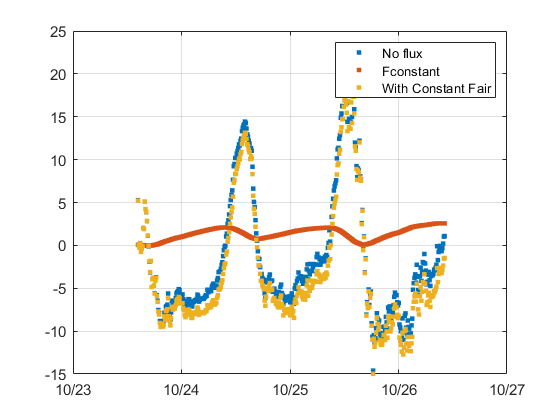


% Calculate constant air-sea gas exchange
% From Needoba Chapter 
% *** Why is this opposite sign of above calcualtion 
% Ca = gasmoleq(pond.sal,pond.temp,'O2'); % mol/m3
% Cw = movmean(pond.DOmeas,nm); % mol/m3      % *** nm is assigned with windspeed smoothing above 

DOmeasper = Cw./Ca*100; 
DOdir = NaN(1,length(dn));
for i = 1:length(dn)
    DOdir(i) = 1 - ((DOmeasper(i) + DOmeasper(i+1))/200);
end

constant = 0.5/31.9988*1000; % g O2/m2/hr to mol 02/m2/hr % From Needoba Chapter 
Fair_constant = DOdir'*constant/6;
delDOdtk = delDOdt0 - Fair_constant; 

figure
plot(dn,delDOdt0,'.','MarkerSize',10) % Uncorrected for air-sea gas exchange
hold on
plot(dn,Fair_constant,'.','MarkerSize',10) % Air-sea gas exchange
plot(dn,delDOdtk,'.','MarkerSize',10) % Corrected for constant air-sea gas exchange
datetick
grid on
legend('No flux','Fconstant','With Constant Fair')

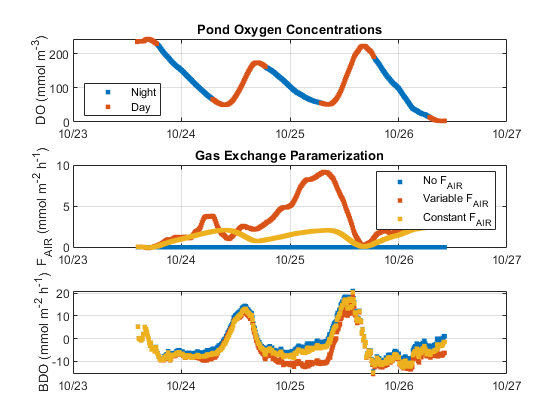

figure 
subplot(3,1,1)
plot(pond.dn(PM),Cw(PM)*1000,'.','MarkerSize',10) % convert to mmol/m3
hold on
plot(pond.dn(AM),Cw(AM)*1000,'.','MarkerSize',10)
datetick
grid on
ylabel('DO (mmol m^-^3)')
title('Pond Oxygen Concentrations')
legend('Night','Day','Location','SW')

subplot(3,1,2)
plot(dn,zeros(1,length(dn)),'.','MarkerSize',10)
hold on
plot(dn,-Fair,'.','MarkerSize',10)
plot(dn,Fair_constant,'.','MarkerSize',10)
datetick
grid on
legend('No F_A_I_R','Variable F_A_I_R','Constant F_A_I_R')
ylabel('F_A_I_R (mmol m^-^2 h^-^1)')
title('Gas Exchange Paramerization')

subplot(3,1,3)
plot(dn,delDOdt0,'.','MarkerSize',10)
hold on
plot(dn,delDOdt,'.','MarkerSize',10)
plot(dn,delDOdtk,'.','MarkerSize',10)
datetick
grid on
ylabel('BDO (mmol m^-^2 h^-^1)')


p.delDOdt = delDOdt;
p.dn = dn;
p.Cw = Cw;
PMpond = PM;
AMpond = AM; 


PM1 = 27:99; % Indices for time periods 
PM2 = 171:243;
PM3 = 315:387;

AM1 = 1:26;
AM2 = 100:170;
AM3 = 244:314;
AM4 = 388:408;

NR1 = sum(delDOdt(PM1))/6 %mmol/m2/hr 

NR1 = -100.5757

NEP1 = sum(delDOdt(AM2))/6 

NEP1 = 21.1612

NR2 = sum(delDOdt(PM2))/6 %mmol/m2/hr 

NR2 = -126.2270

NEP2 = sum(delDOdt(AM3))/6 

NEP2 = 15.3185

NR3 = sum(delDOdt(PM3))/6 %mmol/m2/hr 

NR3 = -120.9796


NEM1 = NEP1 + NR2

NEM1 = -105.0658

NEM2 = NEP2 + NR3

NEM2 = -105.6611


meanR1 = nanmean(delDOdt(PM1))

meanR1 = -8.2665

meanR2 = nanmean(delDOdt(PM2))

meanR2 = -10.3748

meanR3 = nanmean(delDOdt(PM3))

meanR3 = -9.9435


DRR1 = meanR1*24

DRR1 = -198.3959

DRR2 = meanR2*24

DRR2 = -248.9957

DRR3 = meanR3*24

DRR3 = -238.6447


GPP1 = NEP1 + length(AM2)/6*abs(meanR2)

GPP1 = 143.9299

GPP2 = NEP2 + length(AM3)/6*abs(meanR3)

GPP2 = 132.9836

% For Fconstant

NR1 = sum(delDOdtk(PM1))/6 %mmol/m2/hr 

NR1 = -93.6443

NEP1 = sum(delDOdtk(AM2))/6 

NEP1 = 28.9707

NR2 = sum(delDOdtk(PM2))/6 %mmol/m2/hr 

NR2 = -71.7962

NEP2 = sum(delDOdtk(AM3))/6 

NEP2 = 54.7604

NR3 = sum(delDOdtk(PM3))/6 %mmol/m2/hr 

NR3 = -107.7673


NEM1 = NEP1 + NR2

NEM1 = -42.8254

NEM2 = NEP2 + NR3

NEM2 = -53.0069


meanR1 = nanmean(delDOdtk(PM1))

meanR1 = -7.6968

meanR2 = nanmean(delDOdtk(PM2))

meanR2 = -5.9011

meanR3 = nanmean(delDOdtk(PM3))

meanR3 = -8.8576


DRR1 = meanR1*24

DRR1 = -184.7231

DRR2 = meanR2*24

DRR2 = -141.6253

DRR3 = meanR3*24

DRR3 = -212.5821


GPP1 = NEP1 + length(AM2)/6*abs(meanR2)

GPP1 = 98.7999

GPP2 = NEP2 + length(AM3)/6*abs(meanR3)

GPP2 = 159.5752

% For Fair = 0  

NR1 = sum(delDOdt0(PM1))/6 %mmol/m2/hr 

NR1 = -80.3953

NEP1 = sum(delDOdt0(AM2))/6 

NEP1 = 46.8728

NR2 = sum(delDOdt0(PM2))/6 %mmol/m2/hr 

NR2 = -52.9777

NEP2 = sum(delDOdt0(AM3))/6 

NEP2 = 67.7633

NR3 = sum(delDOdt0(PM3))/6 %mmol/m2/hr 

NR3 = -88.1588


NEM1 = NEP1 + NR2

NEM1 = -6.1049

NEM2 = NEP2 + NR3

NEM2 = -20.3956


meanR1 = nanmean(delDOdt0(PM1))

meanR1 = -6.6078

meanR2 = nanmean(delDOdt0(PM2))

meanR2 = -4.3543

meanR3 = nanmean(delDOdt0(PM3))

meanR3 = -7.2459


DRR1 = meanR1*24

DRR1 = -158.5880

DRR2 = meanR2*24

DRR2 = -104.5041

DRR3 = meanR3*24

DRR3 = -173.9024


GPP1 = NEP1 + length(AM2)/6*abs(meanR2)

GPP1 = 98.3991

GPP2 = NEP2 + length(AM3)/6*abs(meanR3)

GPP2 = 153.5068